%문제 3번 

%a
%A = pi*r*sqrt(r^2 + h^2);

%b 
function A = calc_A(r)
    global V
    h = 3*V./(pi*r.^2);
    A = pi*r.*sqrt(r.^2 + h.^2);
end

%c
clc; clear;
global V
V = 10;

r_minA = fminbnd(@calc_A, 0.01, 5) %면적 A가 최소가 되는 r 값

r_minA = 1.8901

A_min = calc_A(r_minA)%면적 A가 가지는 최소값

A_min = 19.4393

h_min = 3*V/(pi*r_minA^2) %그에 따른 높이 h 

h_min = 2.6730

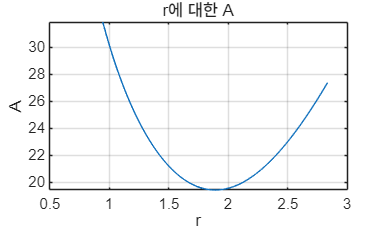


r = linspace(0.5*r_minA, 1.5*r_minA, 200);
A = calc_A(r);
plot(r,A)
xlabel('r')
ylabel('A')
title('r에 대한 A')
grid on 



Alimit = 1.1 * A_min;
f = @(r) calc_A(r) - Alimit;

r1 = fzero(f, [0.01, r_minA]);
r2 = fzero(f, [r_minA, 5]);

r_range = [r1,r2]

r_range =     1.4823    2.3316


%r이 속할 수 있는 구간 
